% Load system parameters from a predefined workspace
load('variables_1D.mat');

% Construct and assess the controllability matrix of the system
ControllabilityMatrix = [B, A*B, A^2*B, A^3*B, A^4*B, A^5*B];
disp("Controllability Matrix Rank:");

Controllability Matrix Rank:


disp(rank(ControllabilityMatrix))

     6



disp((ControllabilityMatrix))

   1.0e-03 *

         0    1.0000         0   -0.1472         0    0.1419
    1.0000         0   -0.1472         0    0.1419         0
         0    0.0500         0   -0.0319         0    0.0227
    0.0500         0   -0.0319         0    0.0227         0
         0    0.1000         0   -0.1128         0    0.1249
    0.1000         0   -0.1128         0    0.1249         0



    disp("If rank is full, the system is controllable.")

If rank is full, the system is controllable.


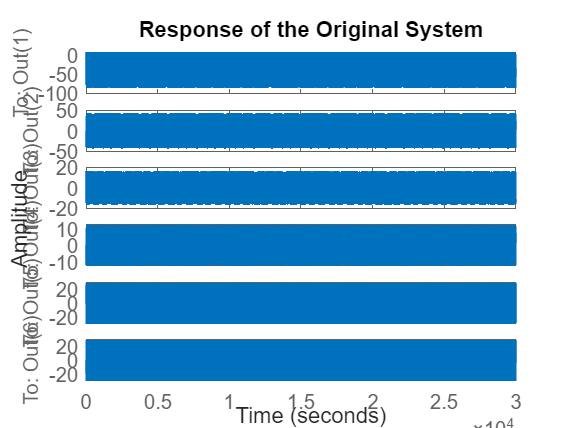


% Define initial state conditions
InitialStateVec = [8; 0; 16; 0; 24; 0];

% Define Q and R for LQR optimization
Q_LQR = diag([10, 20, 30, 40, 50, 60]);
R_LQR = 0.0085;

% Define output matrix (C) and feedthrough matrix (D)
OutputMatrix = eye(6);
DirectTransmission = 0;

% Analyze the original system's response
OrigSysModel = ss(A, B, OutputMatrix, DirectTransmission);
figure;
initial(OrigSysModel, InitialStateVec);
title('Response of the Original System');


% Compute the LQR controller parameters
[LQR_Gain, PosDefMatrix, SystemEig] = lqr(A, B, Q_LQR, R_LQR);

% Display the computed LQR parameters
disp('LQR Feedback Gain Matrix:');

LQR Feedback Gain Matrix:


disp(LQR_Gain);

   34.2997  290.6784  -23.0265 -320.8216   -2.4725 -134.1412



disp('Positive Definite Matrix:');

Positive Definite Matrix:


disp(PosDefMatrix);

   1.0e+04 *

    0.0085    0.0349   -0.0094   -0.0569   -0.0039   -0.0291
    0.0349    0.2972   -0.0223   -0.5016   -0.0041   -0.2504
   -0.0094   -0.0223    1.6693    0.0417    0.0484    0.0067
   -0.0569   -0.5016    0.0417    3.9358    0.0299    0.3213
   -0.0039   -0.0041    0.0484    0.0299    1.0691    0.0046
   -0.0291   -0.2504    0.0067    0.3213    0.0046    1.2035



disp('Eigenvalues of the A-BK System:');

Eigenvalues of the A-BK System:


disp(SystemEig);

  -0.0030 + 0.7284i
  -0.0030 - 0.7284i
  -0.0067 + 1.0428i
  -0.0067 - 1.0428i
  -0.1209 + 0.1183i
  -0.1209 - 0.1183i



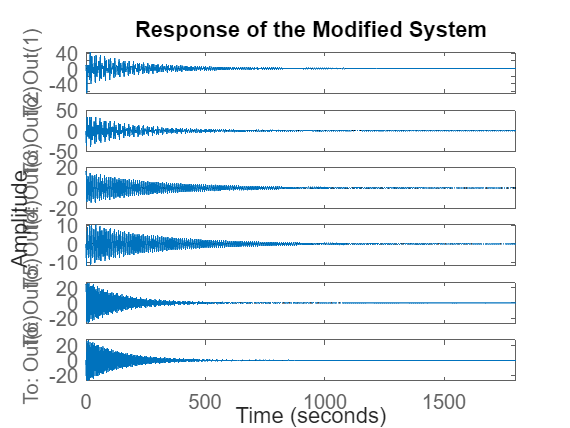


% Adjust A matrix with LQR feedback and analyze the modified system's response
AdjustedA = A - (B * LQR_Gain);
ModifiedSysModel = ss(AdjustedA, B, OutputMatrix, DirectTransmission);
figure;
initial(ModifiedSysModel, InitialStateVec);
title('Response of the Modified System');

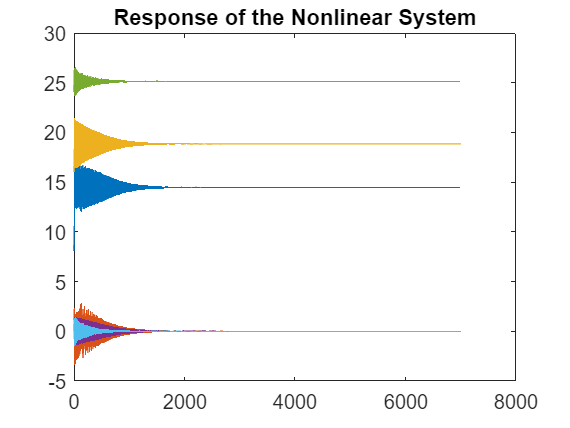


% Simulate and plot the response of the nonlinear system
TimeSpan = 0:0.1:7000;
[T_Sim, X_Sim] = ode45(@(t, X) nonlinearSystem(t, X, LQR_Gain), TimeSpan, InitialStateVec);
figure;
plot(T_Sim, X_Sim);
title('Response of the Nonlinear System');


% Definition of nonlinear system dynamics for ODE solver

function dXdt = nonlinearSystem(t, X, LQR_Gain)
    % Define system parameters
    CraneMass = 1000;
    LoadMass1 = 100; 
    LoadMass2 = 100;
    CableLen1 = 20; 
    CableLen2 = 10;
    GravAcc = 9.81;

    % System matrices A and B
    A_sys = [0 1 0 0 0 0;
             0 0 -(LoadMass1*GravAcc)/CraneMass 0 -(LoadMass2*GravAcc)/CraneMass 0;
             0 0 0 1 0 0;
             0 0 -((CraneMass+LoadMass1)*GravAcc)/(CraneMass*CableLen1) 0 -(LoadMass2*GravAcc)/(CraneMass*CableLen1) 0;
             0 0 0 0 0 1;
             0 0 -(LoadMass1*GravAcc)/(CraneMass*CableLen2) 0 -(GravAcc*(CraneMass+LoadMass2))/(CraneMass*CableLen2) 0];
    B_sys = [0; 1/CraneMass; 0; 1/(CraneMass*CableLen1); 0; 1/(CraneMass*CableLen2)];

    % Compute the control force using LQR gain
    ControlForce = -LQR_Gain * X;

    % Dynamics of the nonlinear system
    dXdt = zeros(6, 1);
    dXdt(1) = X(2);
    dXdt(2) = (ControlForce - (GravAcc/2)*(LoadMass1*sin(2*X(3))+LoadMass2*sin(2*X(5))) - ...
               (LoadMass1*CableLen1*(X(4)^2)*sin(X(3))) - (LoadMass2*CableLen2*(X(6)^2)*sin(X(5)))) / ...
               (CraneMass + LoadMass1*(sin(X(3))^2) + LoadMass2*(sin(X(5))^2));
    dXdt(3) = X(4);
    dXdt(4) = (dXdt(2)*cos(X(3))-GravAcc*sin(X(3)))/CableLen1;
    dXdt(5) = X(6);
    dXdt(6) = (dXdt(2)*cos(X(5))-GravAcc*sin(X(5)))/CableLen2;
end
